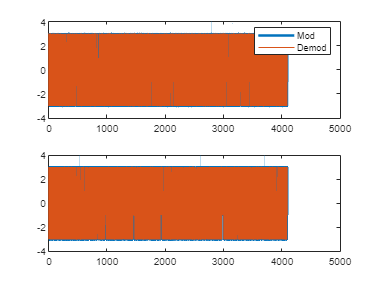

clear;clc;close all;
Nfft = 4096;
M = 16;
ofdm_symbols = 16;
data = randsrc(length(1:Nfft),1,0:M-1);
mod_data = qammod(data,M);
y = ifft(ifftshift(mod_data),Nfft);
y = y*4000;
y_re = real(y);
y_im = imag(y);
demod_data = fft(complex(int16(y_re),int16(y_im)),uint16(Nfft));
demod_data = Fftshift(complex(real((demod_data)),imag((demod_data))));
%demod_data = fft(y,Nfft);
demod_data = demod_data/4000;
figure(),subplot(2,1,1),plot(real(mod_data),'LineWidth',2),hold on,plot(real(demod_data)),legend('Mod','Demod')
subplot(2,1,2),plot(imag(mod_data),'LineWidth',2),hold on,plot(imag(demod_data))